# Create a chiral optical field with a annular subzone vortex phase plate

This live scrtip demonstrates how to generate chiral optical fields using annular subzone vortex phase plates with the `otslm.simple.chiralAsvpp` function.  These beams are described in Dahai Yang et al., Chiral optical field generated by an annular subzone vortex phase plate.  Optics Letters Vol. 43, Issue 19, pp. 4594-4597 (2018) [https://doi.org/10.1364/OL.43.004594.](https://doi.org/10.1364/OL.43.004594.)

## Parameters describing the phase plate

addpath('../../');  % Add OTSLM to path
sz = [512, 512];    % Size of the simulation patterns
radius = 181% Radius of pattern (pixels)

radius = 181

eta = 0.03% Annular lens gradient

eta = 0.0300

lmodes = 1:3:20    % Azimuthal modes of subzones

lmodes =      1     4     7    10    13    16    19


## Generate the phase pattern

pattern = otslm.simple.chiralAsvpp(sz, lmodes, 'eta', eta, 'radius', radius, ...
    'background', 'checkerboard');
subplot(1, 2, 1);
imagesc(mod(pattern, 1));
axis image;
title('Phase pattern')

## Generate visualisation of optical field

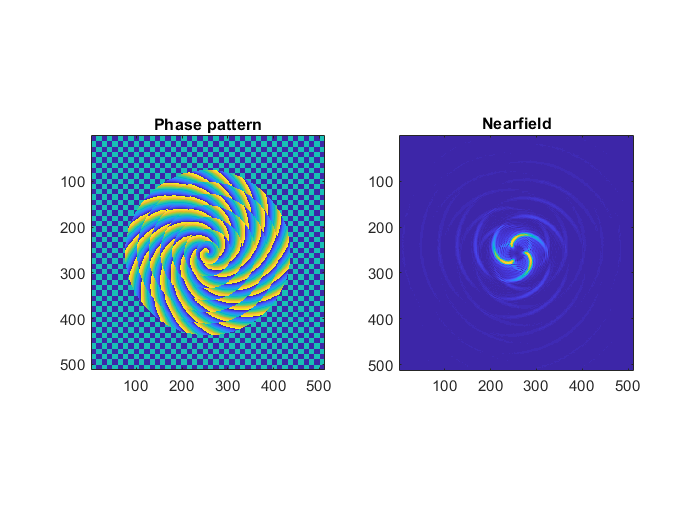

nearfield = otslm.tools.visualise(2*pi*pattern, 'trim_padding', true);
subplot(1, 2, 2);
imagesc(abs(nearfield));
axis image;
title('Nearfield');